# Tuning Curve Width - Current Injection

Analyzes tuning curves from current clamp recordings. Different sections look at spikes, Vm, and the two together. The relevant analysis condition is called "_ManyVms" for the moving bar stimulus.

The beginning of this script also contains a preprocessing step to separate out hyperpolarized vs depolarized epochs. This must be done only once per cell

If you want to look at Vm tuning curves at all, you also have to isolate Vm responses using the scripts located in "MembraneTracesForIgor" folder. Run the first few sections of this script first and save upEpochNumsByCell and downEpochNumsByCell variables (overwrite the upEpochNums.mat and downEpochNums.mat files in the MembraneTracesForIgor folder). Then run the preprocessing script that is also located in that folder. Finally, run the ExtractVms.mlapp app in order to extract the underlying membrane potentials.

ups = grabFromFilter('UP Cells');
downs = grabFromFilter('DOWN Cells');

%User controls:
adjustAllValues = false; %If checked,this will open the setCutoff app for all cells (including previously analyzed cells).

%THERE ARE MULTIPLE VERSIONS OF THE CUTOFF VALUES THAT YOU CAN CHOOSE. THE
%ORIGINAL ONE (cutoffValues.mat) TAKES THE MOST EXTREME DEPOLARIZED AND
%HYPERPOLARIZED EPOCHS. cutoffValues_lessHyperpolarized.mat TAKES LESS
%HYPERPOLARIZED EPOCHS FOR THE HYPERPOLARIZED VERSIONS (if they're
%available). cutoffValues_baseline.mat TAKES THE MOST UNMANIPULATED VERSION
%(BASELINE vM AROUND -55)
cutoffFname = 'cutoffValues_baseline.mat'; %choose which cutoff value file to use here

cutoffFilePath = ['C:\Users\mrsco\Box\Completed_Analysis\WholeCell\CurrentInjections\' cutoffFname];
load([cutoffFilePath]);

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'}; %first field name shosuld be one of these. Priority is in given order
priorityOrder_2 = {'_SP10'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'CurrentClamp', 'PotassiumSpikes', '_ManyVms'};
cantHave_1 = [];
cantHave_2 = {'Cesium'}; %avoid anything with these tags
rigMandates = []; %no rig mandates

upHPCurves = [];
upDPCurves = [];
upHPVms = [];
upDPVms = [];
upHPDSIs = [];
upDPDSIs = [];
upHPpreferredDirections = [];
upDPpreferredDirections = [];
upEpochNumsByCell = {};
upNames = {};
for i = 1:size(ups)
    struct_i = ups{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    
    Vms = loc.Analysis_Results.restingMembranePotentialByEpoch;
    cname = struct_i.cellID;
    
    %determine whether cutoff values have been set for this cell yet
    found = 0;
    for j = 1:size(cutoffValues, 1)
        if strcmp(cname, cutoffValues{j, 1})
            found = 1;
            cutoffs = cutoffValues{j, 2};
            break
        end
    end
    
    %If cutoff values have not yet been set, the user will have to set them
    if ~found %|| strcmp(cname, 'SHOKR80Lc10') %uncomment to change cutoffs for a specific cell
        openApp = setCutoffs(Vms);
        disp(['Set Values for ', cname])
        while isvalid(openApp)
            pause(0.1); %wait for the gui to close, it should send a variable called 'cutoffs' to the workspace when it does
        end
        addIndex = size(cutoffValues, 1) + 1;
        for j = 1:size(cutoffValues, 1)
            if strcmp(cutoffValues{j, 1}, cname)
                addIndex = j;
                break
            end
        end
        cutoffValues(addIndex, 1) = {cname};
        cutoffValues{addIndex, 2} = cutoffs;
    end
    
    %this section will run if the cell has been previously examined AND the
    %user wants the opportunity to adjust its values.
    if adjustAllValues && found
        addIndex = size(cutoffValues, 1) + 1;
        currentCutoffs = [];
        for j = 1:size(cutoffValues, 1)
            if strcmp(cutoffValues{j, 1}, cname)
                addIndex = j;
                currentCutoffs = cutoffValues{j, 2};
                break
            end
        end
        openApp = setCutoffs(Vms, currentCutoffs);
        disp(['Set Values for ', cname])
        while isvalid(openApp)
            pause(0.1); %wait for the gui to close, it should send a variable called 'cutoffs' to the workspace when it does
        end
        cutoffValues(addIndex, 1) = {cname};
        cutoffValues{addIndex, 2} = cutoffs;
    end
    
    upEpochNumsByCell(end + 1, 1) = {cname};
    hpEpochs = Vms>= cutoffs(1) & Vms <= cutoffs(2); %get hyperpolarazation epochs
    dpEpochs = Vms >= cutoffs(3) & Vms <= cutoffs(4); %get depolarization epochs
    
    upEpochNumsByCell(end, 2) = {loc.Analysis_Results.EpochNumbers(hpEpochs)};
    upEpochNumsByCell(end, 3) = {loc.Analysis_Results.orientationByEpoch(hpEpochs)};
    upEpochNumsByCell(end, 4) = {loc.Analysis_Results.EpochNumbers(dpEpochs)};
    upEpochNumsByCell(end, 5) = {loc.Analysis_Results.orientationByEpoch(dpEpochs)};
    
    %write down the direction of each epoch in each category
    hpDirections = loc.Analysis_Results.orientationByEpoch(hpEpochs);
    dpDirections = loc.Analysis_Results.orientationByEpoch(dpEpochs);
    
    %build a template response matrix. This is an nx3 matrix where n = the
    %number of directions probed in the stimulus. Column 1 is simply each direction
    %Column 2 is the sum of the total number of spikes across all epochs for the
    %corresponding direction. Column 3 is the number of epochs for that
    %direction. The average tuning curve is found by dividing column 2 by
    %column 3.
    allDirections = loc.Analysis_Results.Orientation;
    allDirections = sort(allDirections);
    responseMatrix = zeros(numel(allDirections), 3);
    responseMatrix(:, 1) = allDirections;
    
    hpResponseMatrix = responseMatrix;
    hpSpikeTimes = loc.Analysis_Results.allSpikeTimes(hpEpochs);
    for j = 1:numel(hpSpikeTimes)
        numSpikes = numel(hpSpikeTimes{j});
        direction = hpDirections(j);
        index = hpResponseMatrix(:, 1) == direction;
        hpResponseMatrix(index, 2:3) = [hpResponseMatrix(index, 2:3)] + [numSpikes, 1];
    end
    
    
    dpResponseMatrix = responseMatrix;
    dpSpikeTimes = loc.Analysis_Results.allSpikeTimes(dpEpochs);
    for j = 1:numel(dpSpikeTimes)
        numSpikes = numel(dpSpikeTimes{j});
        direction = dpDirections(j);
        index = dpResponseMatrix(:, 1) == direction;
        dpResponseMatrix(index, 2:3) = [dpResponseMatrix(index, 2:3)] + [numSpikes, 1];
    end
    
    %     if min(hpResponseMatrix(:, 3)) < 2 || min(dpResponseMatrix(:, 3)) < 2
    %         continue %skip this cell if there aren't at least 2 epochs in each direction for each condition
    %     end
    
    %find the mean tuning curves
    hpTuningCurve = (hpResponseMatrix(:, 2)./hpResponseMatrix(:, 3))';
    dpTuningCurve = (dpResponseMatrix(:, 2)./dpResponseMatrix(:, 3))';
    
    %calculate the DSI and vector
    [hpDSI, hpVector] = calculateDSI(allDirections, hpTuningCurve);
    [dpDSI, dpVector] = calculateDSI(allDirections, dpTuningCurve);
    
    %write down the information
    upHPCurves(end+1, :) = hpTuningCurve;
    upDPCurves(end+1, :) = dpTuningCurve;
    upHPVms(end + 1, :) = mean(Vms(hpEpochs));
    upDPVms(end + 1, :) = mean(Vms(dpEpochs));
    upHPDSIs(end+1, 1) = hpDSI;
    upDPDSIs(end+1, 1) = dpDSI;
    upHPpreferredDirections(end+1, 1) = mod(hpVector(1), 360);
    upDPpreferredDirections(end+1, 1) = mod(dpVector(1), 360);
    upNames{end + 1} = struct_i.cellID;
end

Set Values for SHOKR80Lc4


Set Values for SHOKR80Lc5


Set Values for SHOKR80Lc7


Set Values for SHOKR80Lc10


Set Values for SHOKR80Lc11


Set Values for SHOKR81Lc6


Set Values for SHOKR81Lc9


Set Values for SHOKR84Lc4


Set Values for SHOKR84Lc7


Set Values for SHOKR84Lc11


Set Values for SHOKR92Lc4



downHPCurves = [];
downDPCurves = [];
downHPVms = [];
downDPVms = [];
downHPDSIs = [];
downDPDSIs = [];
downHPpreferredDirections = [];
downDPpreferredDirections = [];
downEpochNumsByCell = {};
downNames = {};
for i = 1:size(downs)
    struct_i = downs{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    
    Vms = loc.Analysis_Results.restingMembranePotentialByEpoch;
    cname = struct_i.cellID;
    
    %determine whether cutoff values have been set for this cell yet
    found = 0;
    for j = 1:size(cutoffValues, 1)
        if strcmp(cname, cutoffValues{j, 1})
            found = 1;
            cutoffs = cutoffValues{j, 2};
            break
        end
    end
    
    %If cutoff values have not yet been set, the user will have to set them
    if ~found
        openApp = setCutoffs(Vms);
        disp(['Set Values for ', cname])
        while isvalid(openApp)
            pause(0.1); %wait for the gui to close, it should send a variable called 'cutoffs' to the workspace when it does
        end
        addIndex = size(cutoffValues, 1) + 1;
        for j = 1:size(cutoffValues, 1)
            if strcmp(cutoffValues{j, 1}, cname)
                addIndex = j;
                break
            end
        end
        cutoffValues(addIndex, 1) = {cname};
        cutoffValues{addIndex, 2} = cutoffs;
    end
    
    %this section will run if the cell has been previously examined AND the
    %user wants the opportunity to adjust its values.
    if adjustAllValues && found
        addIndex = size(cutoffValues, 1) + 1;
        currentCutoffs = [];
        for j = 1:size(cutoffValues, 1)
            if strcmp(cutoffValues{j, 1}, cname)
                addIndex = j;
                currentCutoffs = cutoffValues{j, 2};
                break
            end
        end
        openApp = setCutoffs(Vms, currentCutoffs);
        disp(['Set Values for ', cname])
        while isvalid(openApp)
            pause(0.1); %wait for the gui to close, it should send a variable called 'cutoffs' to the workspace when it does
        end
        cutoffValues(addIndex, 1) = {cname};
        cutoffValues{addIndex, 2} = cutoffs;
    end
    
    downEpochNumsByCell(end + 1, 1) = {cname};
    hpEpochs = Vms>= cutoffs(1) & Vms <= cutoffs(2); %get hyperpolarazation epochs
    dpEpochs = Vms >= cutoffs(3) & Vms <= cutoffs(4); %get depolarization epochs
    
    downEpochNumsByCell(end, 2) = {loc.Analysis_Results.EpochNumbers(hpEpochs)};
    downEpochNumsByCell(end, 3) = {loc.Analysis_Results.orientationByEpoch(hpEpochs)};
    downEpochNumsByCell(end, 4) = {loc.Analysis_Results.EpochNumbers(dpEpochs)};
    downEpochNumsByCell(end, 5) = {loc.Analysis_Results.orientationByEpoch(dpEpochs)};
    
    
    hpDirections = loc.Analysis_Results.orientationByEpoch(hpEpochs);
    dpDirections = loc.Analysis_Results.orientationByEpoch(dpEpochs);
    
    allDirections = loc.Analysis_Results.Orientation;
    allDirections = sort(allDirections);
    responseMatrix = zeros(numel(allDirections), 3);
    responseMatrix(:, 1) = allDirections;
    
    hpResponseMatrix = responseMatrix;
    hpSpikeTimes = loc.Analysis_Results.allSpikeTimes(hpEpochs);
    for j = 1:numel(hpSpikeTimes)
        numSpikes = numel(hpSpikeTimes{j});
        direction = hpDirections(j);
        index = hpResponseMatrix(:, 1) == direction;
        hpResponseMatrix(index, 2:3) = [hpResponseMatrix(index, 2:3)] + [numSpikes, 1];
    end
    
    
    dpResponseMatrix = responseMatrix;
    dpSpikeTimes = loc.Analysis_Results.allSpikeTimes(dpEpochs);
    for j = 1:numel(dpSpikeTimes)
        numSpikes = numel(dpSpikeTimes{j});
        direction = dpDirections(j);
        index = dpResponseMatrix(:, 1) == direction;
        dpResponseMatrix(index, 2:3) = [dpResponseMatrix(index, 2:3)] + [numSpikes, 1];
    end
    
    %     if min(hpResponseMatrix(:, 3)) < 2 || min(dpResponseMatrix(:, 3)) < 2
    %         continue %skip this cell if there aren't at least 2 epochs in each direction for each condition
    %     end
    
    hpTuningCurve = (hpResponseMatrix(:, 2)./hpResponseMatrix(:, 3))';
    dpTuningCurve = (dpResponseMatrix(:, 2)./dpResponseMatrix(:, 3))';
    
    [hpDSI, hpVector] = calculateDSI(allDirections, hpTuningCurve);
    [dpDSI, dpVector] = calculateDSI(allDirections, dpTuningCurve);
    
    downHPCurves(end+1, :) = hpTuningCurve;
    downDPCurves(end+1, :) = dpTuningCurve;
    downHPVms(end + 1, :) = mean(Vms(hpEpochs));
    downDPVms(end + 1, :) = mean(Vms(dpEpochs));
    downHPDSIs(end+1, 1) = hpDSI;
    downDPDSIs(end+1, 1) = dpDSI;
    downHPpreferredDirections(end+1, 1) = mod(hpVector(1), 360);
    downDPpreferredDirections(end+1, 1) = mod(dpVector(1), 360);
    downNames{end + 1} = struct_i.cellID;
end
close all
% epochNumsFilePath = 'C:\Users\mrsco\Box\Completed_Analysis\WholeCell\CurrentInjections\MembraneTracesForIgor';
% save(fullfile(epochNumsFilePath , 'UpEpochNums.mat'), 'upEpochNumsByCell')
% save(fullfile(epochNumsFilePath, 'DownEpochNums.mat'), 'downEpochNumsByCell')
save(cutoffFilePath, 'cutoffValues')
clear ups downs

## Example Cell

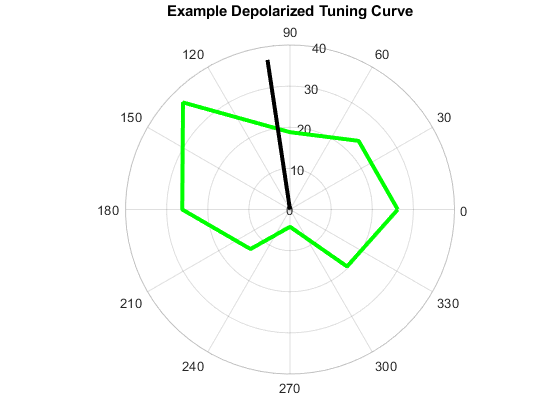

cellNumber = 7; %Choosing up cell #5 as the example

exampleHPCurve = upHPCurves(cellNumber, :);
exampleDPCurve = upDPCurves(cellNumber, :);
HPPD = upHPpreferredDirections(cellNumber);
DPPD = upDPpreferredDirections(cellNumber);

ds = [0:45:360];

figure
polarplot(deg2rad(ds), [exampleDPCurve, exampleDPCurve(1)], 'g', 'linewidth', 3)
hold on
polarplot(deg2rad([DPPD, DPPD]), [0, max(exampleDPCurve)], 'k', 'linewidth', 3)
title('Example Depolarized Tuning Curve')

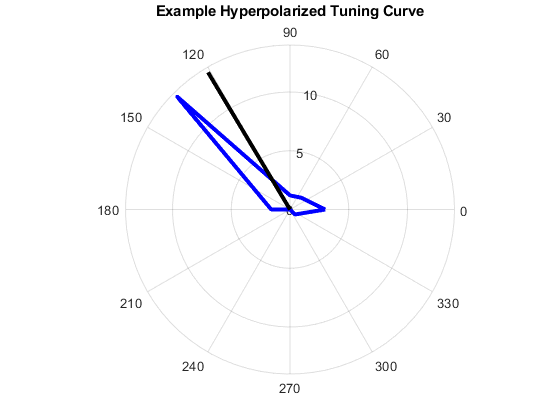



figure
polarplot(deg2rad(ds), [exampleHPCurve, exampleHPCurve(1)], 'b', 'linewidth', 3)
hold on
polarplot(deg2rad([HPPD, HPPD]), [0, max(exampleHPCurve)], 'k', 'linewidth', 3)
title('Example Hyperpolarized Tuning Curve')

## Tuning Curve Widths

stepSize = 0.25; %step size for interpolation in degrees
interpolationMethod = 'linear';
xvals = [allDirections, 360];
interpolationPoints = [0:stepSize:360]; %in degrees

upNormalizedHPCurves = zeros(size(upHPCurves, 1), numel(allDirections)+1);
upNormalizedDPCurves = zeros(size(upDPCurves, 1), numel(allDirections)+1);


for i = 1:size(upHPCurves, 1)
    hpCurve_i = upHPCurves(i, :);
    hpCircularCurve_i = [hpCurve_i, hpCurve_i(1)];
    hpPD = upHPpreferredDirections(i);
    hpPDFR = interp1(xvals, hpCircularCurve_i, hpPD, interpolationMethod);
    
    normalizedHPCurve = hpCircularCurve_i./hpPDFR;
    upNormalizedHPCurves(i, :) = normalizedHPCurve;
    
    dpCurve_i = upDPCurves(i, :);
    dpCircularCurve_i = [dpCurve_i, dpCurve_i(1)];
    dpPD = upDPpreferredDirections(i);
    dpPDFR = interp1(xvals, dpCircularCurve_i, dpPD, interpolationMethod);
    
    normalizedDPCurve = dpCircularCurve_i./dpPDFR;
    upNormalizedDPCurves(i, :) = normalizedDPCurve;
    
end


downNormalizedHPCurves = zeros(size(downHPCurves, 1), numel(allDirections)+1);
downNormalizedDPCurves = zeros(size(downDPCurves, 1), numel(allDirections)+1);

for i = 1:size(downHPCurves, 1)
    hpCurve_i = downHPCurves(i, :);
    hpCircularCurve_i = [hpCurve_i, hpCurve_i(1)];
    hpPD = downHPpreferredDirections(i);
    hpPDFR = interp1(xvals, hpCircularCurve_i, hpPD, interpolationMethod);
    
    normalizedHPCurve = hpCircularCurve_i./hpPDFR;
    downNormalizedHPCurves(i, :) = normalizedHPCurve;
    
    dpCurve_i = downDPCurves(i, :);
    dpCircularCurve_i = [dpCurve_i, dpCurve_i(1)];
    dpPD = downDPpreferredDirections(i);
    dpPDFR = interp1(xvals, dpCircularCurve_i, dpPD, interpolationMethod);
    
    normalizedDPCurve = dpCircularCurve_i./dpPDFR;
    downNormalizedDPCurves(i, :) = normalizedDPCurve;
end

## Normalized Tuning Curve Areas

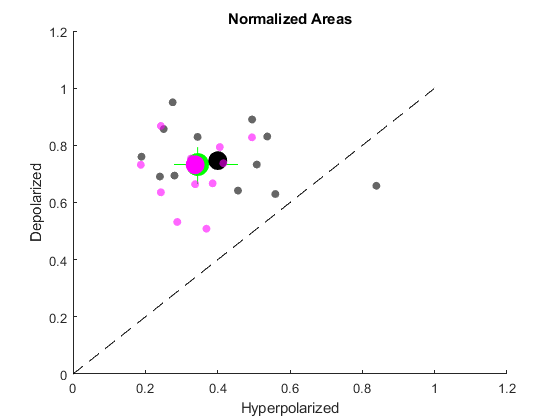

upNormalizedHPAreas = trapz([allDirections, 360], upNormalizedHPCurves, 2)./360;
upNormalizedDPAreas = trapz([allDirections, 360], upNormalizedDPCurves, 2)./360;
downNormalizedHPAreas = trapz([allDirections, 360], downNormalizedHPCurves, 2)./360;
downNormalizedDPAreas = trapz([allDirections, 360], downNormalizedDPCurves, 2)./360;

upCellAttachedMedianNormedArea = 0.6567; %Median area of the tuning curve of up cells from cell attached recordings as of 10/12/2021
downCellAttachedMedianNormedArea = 0.7345; %Median area of the tuning curve of down cells from cell attached recordings as of 10/12/2021


medianX = median([upNormalizedHPAreas; downNormalizedHPAreas]);
medianY = median([upNormalizedDPAreas; downNormalizedDPAreas]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([upNormalizedHPAreas; downNormalizedHPAreas], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([upNormalizedDPAreas; downNormalizedDPAreas], 10000);


figure
title('Normalized Areas')
hold on
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
plot([0, 1], [0, 1], '--k')
scatter(upNormalizedHPAreas, upNormalizedDPAreas, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(upNormalizedHPAreas), median(upNormalizedDPAreas), 200, 'k', 'filled')
scatter(downNormalizedHPAreas, downNormalizedDPAreas, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(downNormalizedHPAreas), median(downNormalizedDPAreas), 200, 'm', 'filled')
xlabel('Hyperpolarized')
ylabel('Depolarized')
xlim([0, 1.2])
ylim([0, 1.2])

p_Up = signrank(upNormalizedHPAreas, upNormalizedDPAreas)

p_Up = 0.0015

p_Down = signrank(downNormalizedHPAreas, downNormalizedDPAreas)

p_Down = 9.7656e-04

p_combined = signrank([upNormalizedHPAreas; downNormalizedHPAreas], [upNormalizedDPAreas; downNormalizedDPAreas])

p_combined = 4.0254e-05

## Area of unnormalized tuning curves

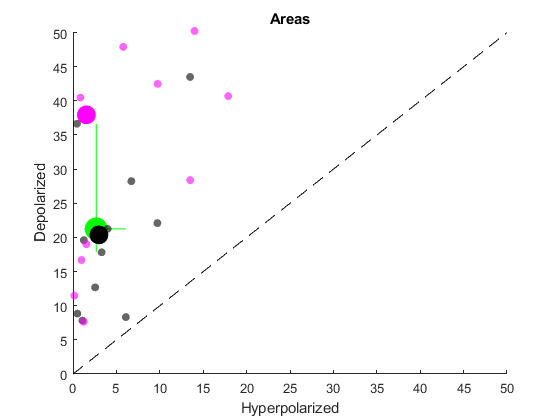

circularHPUp = [upHPCurves, upHPCurves(:, 1)];
circularDPUp = [upDPCurves, upDPCurves(:, 1)];
circularHPDown = [downHPCurves, downHPCurves(:, 1)];
circularDPDown = [downDPCurves, downDPCurves(:, 1)];

areaHPUp = trapz([allDirections, 360], circularHPUp, 2)./360;
areaDPUp = trapz([allDirections, 360], circularDPUp, 2)./360;
areaHPDown = trapz([allDirections, 360], circularHPDown, 2)./360;
areaDPDown = trapz([allDirections, 360], circularDPDown , 2)./360;

upCellAttachedMedianArea = 7803./360; %Median area of the tuning curve of up cells from cell attached recordings as of 10/12/2021
downCellAttachedMedianArea = 11529./360; %Median area of the tuning curve of down cells from cell attached recordings as of 10/12/2021


medianX = median([areaHPUp; areaHPDown]);
medianY = median([areaDPUp; areaDPDown]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([areaHPUp; areaHPDown], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([areaDPUp; areaDPDown], 10000);


figure
title('Areas')
hold on
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
plot([0, 50], [0, 50], '--k')
scatter(areaHPUp, areaDPUp, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(areaHPUp), median(areaDPUp), 200, 'k', 'filled')
scatter(areaHPDown, areaDPDown, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(areaHPDown), median(areaDPDown), 200, 'm', 'filled')
xlabel('Hyperpolarized')
ylabel('Depolarized')
xlim([0, inf])
ylim([0, inf])

p_Up = signrank(areaHPUp, areaDPUp)

p_Up = 4.8828e-04

p_Down = signrank(areaHPDown, areaDPDown)

p_Down = 9.7656e-04

p_Combined = signrank([areaHPUp; areaHPDown], [areaDPUp; areaDPDown])

p_Combined = 2.7016e-05

## DSIs

upMedianDSICellAttached = 0.3016 %Median DSI of up cells from cell attached recordings as of 10/12/20211

upMedianDSICellAttached = 0.3016

downMedianDSICellAttached = 0.2440 %Median DSI of down cells from cell attached recordings as of 10/12/20211

downMedianDSICellAttached = 0.2440

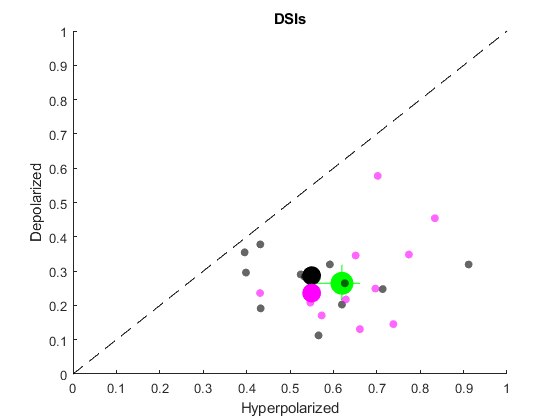

medianX = median([upHPDSIs; downHPDSIs]);
medianY = median([upDPDSIs; downDPDSIs]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([upHPDSIs; downHPDSIs], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([upDPDSIs; downDPDSIs], 10000);


figure
title('DSIs')
hold on
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
plot([0, 1], [0, 1], '--k')
scatter(upHPDSIs, upDPDSIs, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(upHPDSIs), median(upDPDSIs), 200, 'k', 'filled')
scatter(downHPDSIs, downDPDSIs, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(upHPDSIs), median(downDPDSIs), 200, 'm', 'filled')
plot([0, 1], [0, 1], '--k')
xlabel('Hyperpolarized')
ylabel('Depolarized')
xlim([0, 1])
ylim([0, 1])

p_Up = signrank(upHPDSIs, upDPDSIs)

p_Up = 4.8828e-04

p_Down = signrank(downHPDSIs, downDPDSIs)

p_Down = 9.7656e-04

p_Combined = signrank([upHPDSIs; downHPDSIs], [upDPDSIs; downDPDSIs])

p_Combined = 2.7016e-05

## Preferred Directions

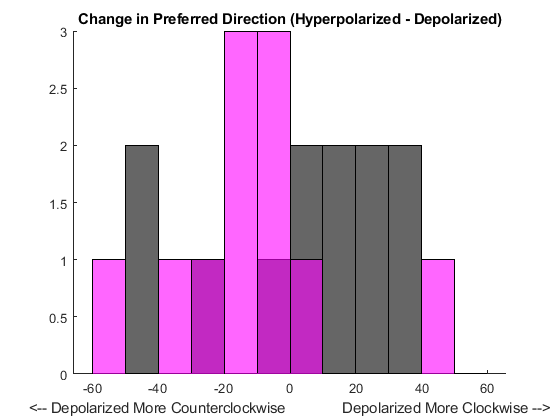

upPDDifs = upHPpreferredDirections - upDPpreferredDirections;
downPDDifs = downHPpreferredDirections - downDPpreferredDirections;

edgs =[-60:10:60];
figure
title('Change in Preferred Direction (Hyperpolarized - Depolarized)')
hold on
histogram(upPDDifs, 'FaceColor', 'k', 'BinEdges', edgs)
histogram(downPDDifs, 'FaceColor', 'm',  'BinEdges', edgs)
xlabel('<-- Depolarized More Counterclockwise              Depolarized More Clockwise -->')

p_Up  = signrank(upPDDifs)

p_Up = 0.7334

p_Down = signrank(downPDDifs)

p_Down = 0.1016

p_Combined = signrank([upPDDifs; -downPDDifs])

p_Combined = 0.1443

## Compare spike tuning curves with Vm tuning curves

dataPath = 'C:\Users\mrsco\Box\Completed_Analysis\WholeCell\CurrentInjections\MembraneTracesForIgor';

cantExtractVmFrom = {'SHOKR80Lc7', 'SHOKR80Lc11', 'SHOKR81Lc7', 'SHOKR81Lc1',...
    'SHOKR81Lc8', 'SHOKR84Lc2'};
requirements = @(cname, dataPath) exist([dataPath, '\', cname], 'dir')...
    && ~ismember(cname, cantExtractVmFrom);%&& (contains(cname, '84') || contains(cname, '80'));

offset = 6; %mV - the offset from resting membrane potential
thresholdDepolarized = 0; %mV - the artificial threshold to apply to membrane potential for thresholded condition
thresholdHyperpolarized = 11; %mV
offsetForThreshold = 0; %the offset value to use for the thresholded analyses

upMax_DSI_hyperpolarized = [];
upMax_DSI_hyperpolarized_offset = []; %accounts for current injection offset.
upMax_DSI_hyperpolarized_threshold = [];
upMax_Area_hyperpolarized = [];
upMax_Area_hyperpolarized_offset = [];
upMax_Area_hyperpolarized_threshold = [];
upMax_NormedArea_hyperpolarized = [];
upMax_NormedArea_hyperpolarized_offset = [];
upMax_NormedArea_hyperpolarized_threshold = [];
upMax_DSI_depolarized = [];
upMax_DSI_depolarized_offset = [];
upMax_DSI_depolarized_threshold = [];
upMax_Area_depolarized = [];
upMax_Area_depolarized_offset = [];
upMax_Area_depolarized_threshold = [];
upMax_NormedArea_depolarized = [];
upMax_NormedArea_depolarized_offset = [];
upMax_NormedArea_depolarized_threshold = [];
up_RestingVm_hyperpolarized = [];
up_RestingVm_hyperpolarized_offset = [];
up_RestingVm_hyperpolarized_threshold = [];
up_RestingVm_depolarized = [];
up_RestingVm_depolarized_offset = [];
up_RestingVm_depolarized_threshold = [];
%Grab the Vm traces for downs and compute DSI and other stats based on peak
%Vm deflection in each direction
goodUps = ones(1, size(upEpochNumsByCell, 1));
for i = 1:size(upEpochNumsByCell, 1)
    cname = upEpochNumsByCell{i, 1};
    if ~requirements(cname, dataPath)
        goodUps(i) = 0;
        continue
    end
    
    try
        load(fullfile(dataPath, cname, 'depolarized_extractedVms.mat')) %loads variable called extractedTraces
        depolarizedTraces = extractedTraces;
        load(fullfile(dataPath, cname, 'hyperpolarized_extractedVms.mat'))
        hyperpolarizedTraces = extractedTraces;
        clear extractedTraces;
    catch
        goodUps(i) = 0;
        continue
    end
    
    hyperpolarizedDirections = upEpochNumsByCell{i, 3};
    depolarizedDirections = upEpochNumsByCell{i, 5};
    
    
    %hyperpolarized condition
    output = VmCurrentInjection_Helper(hyperpolarizedTraces, hyperpolarizedDirections);
    upMax_DSI_hyperpolarized = [upMax_DSI_hyperpolarized, output.DSI_MaxResponses];
    upMax_Area_hyperpolarized = [upMax_Area_hyperpolarized, output.TotalArea_MaxResponses];
    upMax_NormedArea_hyperpolarized = [upMax_NormedArea_hyperpolarized, output.NormalizedArea_MaxResponses];
    up_RestingVm_hyperpolarized = [up_RestingVm_hyperpolarized, output.MeanRestingMembranePotential];
    
    %hyperpolarized condition with offset
    output = VmCurrentInjection_Helper(hyperpolarizedTraces, hyperpolarizedDirections, 'offset', -offset);
    upMax_DSI_hyperpolarized_offset = [upMax_DSI_hyperpolarized_offset, output.DSI_MaxResponses];
    upMax_Area_hyperpolarized_offset = [upMax_Area_hyperpolarized_offset, output.TotalArea_MaxResponses];
    upMax_NormedArea_hyperpolarized_offset = [upMax_NormedArea_hyperpolarized_offset, output.NormalizedArea_MaxResponses];
    up_RestingVm_hyperpolarized_offset = [up_RestingVm_hyperpolarized_offset, output.MeanRestingMembranePotential];
    
    %hyperpolarized condition with threshold
    output = VmCurrentInjection_Helper(hyperpolarizedTraces, hyperpolarizedDirections, 'offset', -offsetForThreshold, 'threshold', thresholdHyperpolarized);
    upMax_DSI_hyperpolarized_threshold = [upMax_DSI_hyperpolarized_threshold, output.DSI_MaxResponses];
    upMax_Area_hyperpolarized_threshold = [upMax_Area_hyperpolarized_threshold, output.TotalArea_MaxResponses];
    upMax_NormedArea_hyperpolarized_threshold = [upMax_NormedArea_hyperpolarized_threshold, output.NormalizedArea_MaxResponses];
    up_RestingVm_hyperpolarized_threshold = [up_RestingVm_hyperpolarized_threshold, output.MeanRestingMembranePotential];
    
    %depolarized condition
    output = VmCurrentInjection_Helper(depolarizedTraces, depolarizedDirections);
    upMax_DSI_depolarized = [upMax_DSI_depolarized, output.DSI_MaxResponses];
    upMax_Area_depolarized = [upMax_Area_depolarized, output.TotalArea_MaxResponses];
    upMax_NormedArea_depolarized = [upMax_NormedArea_depolarized, output.NormalizedArea_MaxResponses];
    up_RestingVm_depolarized = [up_RestingVm_depolarized, output.MeanRestingMembranePotential];
    
    %depolarized condition with offset
    output = VmCurrentInjection_Helper(depolarizedTraces, depolarizedDirections, 'offset', offset);
    upMax_DSI_depolarized_offset = [upMax_DSI_depolarized_offset, output.DSI_MaxResponses];
    upMax_Area_depolarized_offset = [upMax_Area_depolarized_offset, output.TotalArea_MaxResponses];
    upMax_NormedArea_depolarized_offset = [upMax_NormedArea_depolarized_offset, output.NormalizedArea_MaxResponses];
    up_RestingVm_depolarized_offset = [up_RestingVm_depolarized_offset, output.MeanRestingMembranePotential];
    
    %depolarized condition with threshold
    output = VmCurrentInjection_Helper(depolarizedTraces, depolarizedDirections, 'offset', offsetForThreshold, 'threshold', thresholdDepolarized);
    upMax_DSI_depolarized_threshold = [upMax_DSI_depolarized_threshold, output.DSI_MaxResponses];
    upMax_Area_depolarized_threshold = [upMax_Area_depolarized_threshold, output.TotalArea_MaxResponses];
    upMax_NormedArea_depolarized_threshold = [upMax_NormedArea_depolarized_threshold, output.NormalizedArea_MaxResponses];
    up_RestingVm_depolarized_threshold = [up_RestingVm_depolarized_threshold, output.MeanRestingMembranePotential];
    % Use this to make polar plots for individual cells
    %     if strcmp(cname, 'SHOKR81Lc9')
    %         a = 1;
    %         thetas = deg2rad([0:45:360]);
    %         [~, vector] = calculateDSI([0:45:315], output.MaxResponsesByDirection)
    %          polarplot([0, deg2rad(vector(1))], [0, vector(2)], 'r')
    %          hold on
    %         polarplot(thetas, [output.MaxResponsesByDirection, output.MaxResponsesByDirection(1)])
    %
    %     end
end
clear depolarizedTraces hyperpolarizedTraces
%repeat for downs
downMax_DSI_hyperpolarized = [];
downMax_DSI_hyperpolarized_offset = []; %accounts for current injection offset.
downMax_DSI_hyperpolarized_threshold = [];
downMax_Area_hyperpolarized = [];
downMax_Area_hyperpolarized_offset = [];
downMax_Area_hyperpolarized_threshold = [];
downMax_NormedArea_hyperpolarized = [];
downMax_NormedArea_hyperpolarized_offset = [];
downMax_NormedArea_hyperpolarized_threshold = [];
downMax_DSI_depolarized = [];
downMax_DSI_depolarized_offset = [];
downMax_DSI_depolarized_threshold = [];
downMax_Area_depolarized = [];
downMax_Area_depolarized_offset = [];
downMax_Area_depolarized_threshold = [];
downMax_NormedArea_depolarized = [];
downMax_NormedArea_depolarized_offset = [];
downMax_NormedArea_depolarized_threshold = [];
down_RestingVm_hyperpolarized = [];
down_RestingVm_hyperpolarized_offset = [];
down_RestingVm_hyperpolarized_threshold = [];
down_RestingVm_depolarized = [];
down_RestingVm_depolarized_offset = [];
down_RestingVm_depolarized_threshold = [];

goodDowns = ones(1, size(downEpochNumsByCell, 1));
for i = 1:size(downEpochNumsByCell, 1)
    cname = downEpochNumsByCell{i, 1};
    if ~requirements(cname, dataPath)
        goodDowns(i) = 0;
        continue
    end
    
    try
        load(fullfile(dataPath, cname, 'depolarized_extractedVms.mat'))
        depolarizedTraces = extractedTraces;
        load(fullfile(dataPath, cname, 'hyperpolarized_extractedVms.mat'))
        hyperpolarizedTraces = extractedTraces;
        clear extractedTraces;
    catch
        goodDowns(i) = 0;
        continue
    end
    
    hyperpolarizedDirections = downEpochNumsByCell{i, 3};
    depolarizedDirections = downEpochNumsByCell{i, 5};
    
    output = VmCurrentInjection_Helper(hyperpolarizedTraces, hyperpolarizedDirections);
    %hyperpolarized condition
    downMax_DSI_hyperpolarized = [downMax_DSI_hyperpolarized, output.DSI_MaxResponses];
    downMax_Area_hyperpolarized = [downMax_Area_hyperpolarized, output.TotalArea_MaxResponses];
    downMax_NormedArea_hyperpolarized = [downMax_NormedArea_hyperpolarized, output.NormalizedArea_MaxResponses];
    down_RestingVm_hyperpolarized = [down_RestingVm_hyperpolarized, output.MeanRestingMembranePotential];
    
    %hyperpolarized condition with offset
    output = VmCurrentInjection_Helper(hyperpolarizedTraces, hyperpolarizedDirections, 'offset', -offset);
    downMax_DSI_hyperpolarized_offset = [downMax_DSI_hyperpolarized_offset, output.DSI_MaxResponses];
    downMax_Area_hyperpolarized_offset = [downMax_Area_hyperpolarized_offset, output.TotalArea_MaxResponses];
    downMax_NormedArea_hyperpolarized_offset = [downMax_NormedArea_hyperpolarized_offset, output.NormalizedArea_MaxResponses];
    down_RestingVm_hyperpolarized_offset = [down_RestingVm_hyperpolarized_offset, output.MeanRestingMembranePotential];
    
    %hyperpolarized condition with threshold
    output = VmCurrentInjection_Helper(hyperpolarizedTraces, hyperpolarizedDirections, 'offset', -offsetForThreshold, 'threshold', thresholdHyperpolarized  );
    downMax_DSI_hyperpolarized_threshold = [downMax_DSI_hyperpolarized_threshold, output.DSI_MaxResponses];
    downMax_Area_hyperpolarized_threshold = [downMax_Area_hyperpolarized_threshold, output.TotalArea_MaxResponses];
    downMax_NormedArea_hyperpolarized_threshold = [downMax_NormedArea_hyperpolarized_threshold, output.NormalizedArea_MaxResponses];
    down_RestingVm_hyperpolarized_threshold = [down_RestingVm_hyperpolarized_threshold, output.MeanRestingMembranePotential];
    
    %depolarized condition
    output = VmCurrentInjection_Helper(depolarizedTraces, depolarizedDirections);
    downMax_DSI_depolarized = [downMax_DSI_depolarized, output.DSI_MaxResponses];
    downMax_Area_depolarized = [downMax_Area_depolarized, output.TotalArea_MaxResponses];
    downMax_NormedArea_depolarized = [downMax_NormedArea_depolarized, output.NormalizedArea_MaxResponses];
    down_RestingVm_depolarized = [down_RestingVm_depolarized, output.MeanRestingMembranePotential];
    
    %depolarized condition with offset
    output = VmCurrentInjection_Helper(depolarizedTraces, depolarizedDirections, 'offset', offset);
    downMax_DSI_depolarized_offset = [downMax_DSI_depolarized_offset, output.DSI_MaxResponses];
    downMax_Area_depolarized_offset = [downMax_Area_depolarized_offset, output.TotalArea_MaxResponses];
    downMax_NormedArea_depolarized_offset = [downMax_NormedArea_depolarized_offset, output.NormalizedArea_MaxResponses];
    down_RestingVm_depolarized_offset = [down_RestingVm_depolarized_offset, output.MeanRestingMembranePotential];
    
    %depolarized condition with threshold
    output = VmCurrentInjection_Helper(depolarizedTraces, depolarizedDirections, 'offset', offsetForThreshold, 'threshold', thresholdDepolarized);
    downMax_DSI_depolarized_threshold = [downMax_DSI_depolarized_threshold, output.DSI_MaxResponses];
    downMax_Area_depolarized_threshold = [downMax_Area_depolarized_threshold, output.TotalArea_MaxResponses];
    downMax_NormedArea_depolarized_threshold = [downMax_NormedArea_depolarized_threshold, output.NormalizedArea_MaxResponses];
    down_RestingVm_depolarized_threshold = [down_RestingVm_depolarized_threshold, output.MeanRestingMembranePotential];
end
clear depolarizedTraces  HyperpolarizedTraces

%these variables are important. They tell you which cells that have had
%spike analyses also had voltage analyses by giving you the indices to use
%to pull data from the spike data.
goodUpIndices = find(goodUps);
goodDownIndices = find(goodDowns);

upSpikeHypDep_DSI = zeros(4, numel(upMax_DSI_hyperpolarized));
upSpikeHypDep_NormedArea = zeros(4, numel(upMax_DSI_hyperpolarized));
for i = 1:size(upSpikeHypDep_DSI, 2)
    upSpikeHypDep_DSI(1, i) = upHPDSIs(goodUpIndices(i));
    upSpikeHypDep_DSI(2, i) = upMax_DSI_hyperpolarized(i);
    upSpikeHypDep_DSI(3, i) = upDPDSIs(goodUpIndices(i));
    upSpikeHypDep_DSI(4, i) = upMax_DSI_depolarized(i);
    
    upSpikeHypDep_NormedArea(1, i) = upNormalizedHPAreas(goodUpIndices(i));
    upSpikeHypDep_NormedArea(2, i) = upMax_NormedArea_hyperpolarized(i);
    upSpikeHypDep_NormedArea(3, i) = upNormalizedDPAreas(goodUpIndices(i));
    upSpikeHypDep_NormedArea(4, i) = upMax_NormedArea_depolarized(i);
end


downSpikeHypDep_DSI = zeros(4, numel(downMax_DSI_hyperpolarized));
downSpikeHypDep_NormedArea = zeros(4, numel(downMax_DSI_hyperpolarized));
for i = 1:size(downSpikeHypDep_DSI, 2)
    downSpikeHypDep_DSI(1, i) = downHPDSIs(goodDownIndices(i));
    downSpikeHypDep_DSI(2, i) = downMax_DSI_hyperpolarized(i);
    downSpikeHypDep_DSI(3, i) = downDPDSIs(goodDownIndices(i));
    downSpikeHypDep_DSI(4, i) = downMax_DSI_depolarized(i);
    
    downSpikeHypDep_NormedArea(1, i) = downNormalizedHPAreas(goodDownIndices(i));
    downSpikeHypDep_NormedArea(2, i) = downMax_NormedArea_hyperpolarized(i);
    downSpikeHypDep_NormedArea(3, i) = downNormalizedDPAreas(goodDownIndices(i));
    downSpikeHypDep_NormedArea(4, i) = downMax_NormedArea_depolarized(i);
end

clear cellList



## Compare hyperpolarized and depolarized Vm tuning curves

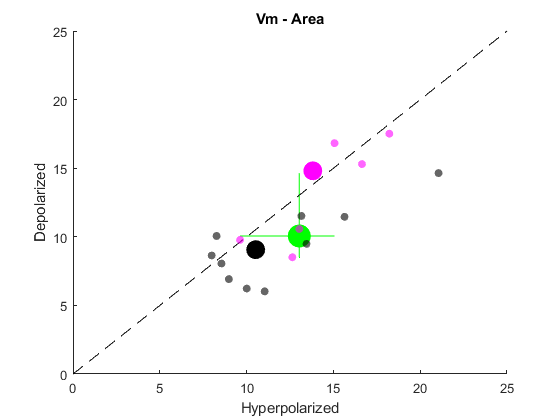


medianX = median([upMax_Area_hyperpolarized, downMax_Area_hyperpolarized]);
medianY = median([upMax_Area_depolarized, downMax_Area_depolarized]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([upMax_Area_hyperpolarized, downMax_Area_hyperpolarized], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([upMax_Area_depolarized, downMax_Area_depolarized], 10000);


figure
title('Vm - Area')
hold on
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
plot([0, 25], [0, 25], '--k')
scatter(upMax_Area_hyperpolarized, upMax_Area_depolarized, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(upMax_Area_hyperpolarized), median(upMax_Area_depolarized), 200, 'k', 'filled')
scatter(downMax_Area_hyperpolarized, downMax_Area_depolarized, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(downMax_Area_hyperpolarized), median(downMax_Area_depolarized), 200, 'm', 'filled')
xlabel('Hyperpolarized')
ylabel('Depolarized')
xlim([0, 25])
ylim([0, 25])


p_Vm_Area = signrank([downMax_Area_hyperpolarized-downMax_Area_depolarized,...
    upMax_Area_hyperpolarized-upMax_Area_depolarized])

p_Vm_Area = 0.0168

p_UpVsDown_hyperpolarized = ranksum(downMax_Area_hyperpolarized, upMax_Area_hyperpolarized)

p_UpVsDown_hyperpolarized = 0.1613

p_UpVsDown_depolarized = ranksum(downMax_Area_depolarized, upMax_Area_depolarized)

p_UpVsDown_depolarized = 0.0330

meanAreasUp = mean([upMax_Area_hyperpolarized;upMax_Area_depolarized]);
meanAreasDown =mean([downMax_Area_hyperpolarized;downMax_Area_depolarized]);
p_UpVsDown_Mean = ranksum(meanAreasUp, meanAreasDown)

p_UpVsDown_Mean = 0.0431

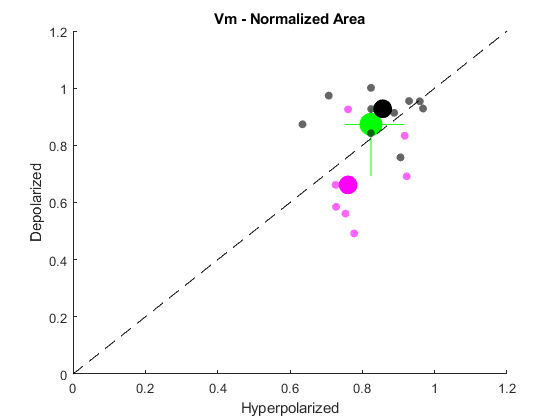


medianX = median([upMax_NormedArea_hyperpolarized, downMax_NormedArea_hyperpolarized]);
medianY = median([upMax_NormedArea_depolarized, downMax_NormedArea_depolarized]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([upMax_NormedArea_hyperpolarized, downMax_NormedArea_hyperpolarized], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([upMax_NormedArea_depolarized, downMax_NormedArea_depolarized], 10000);


figure
title('Vm - Normalized Area')
hold on
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
plot([0, 1.2], [0, 1.2], '--k')
scatter(upMax_NormedArea_hyperpolarized, upMax_NormedArea_depolarized, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(upMax_NormedArea_hyperpolarized), median(upMax_NormedArea_depolarized), 200, 'k', 'filled')
scatter(downMax_NormedArea_hyperpolarized, downMax_NormedArea_depolarized, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(downMax_NormedArea_hyperpolarized), median(downMax_NormedArea_depolarized), 200, 'm', 'filled')
xlabel('Hyperpolarized')
ylabel('Depolarized')
xlim([0, 1.2])
ylim([0, 1.2])

p_Vm_NormedArea = signrank([downMax_NormedArea_hyperpolarized-downMax_NormedArea_depolarized,...
    upMax_NormedArea_hyperpolarized-upMax_NormedArea_depolarized])

p_Vm_NormedArea = 0.7946


meanNormedAreaUp = mean([upMax_NormedArea_hyperpolarized; upMax_NormedArea_depolarized]);
meanNormedAreaDown =mean([downMax_NormedArea_hyperpolarized; downMax_NormedArea_depolarized]);
p_UpVsDown_Mean = ranksum(meanNormedAreaUp, meanNormedAreaDown)

p_UpVsDown_Mean = 0.0097

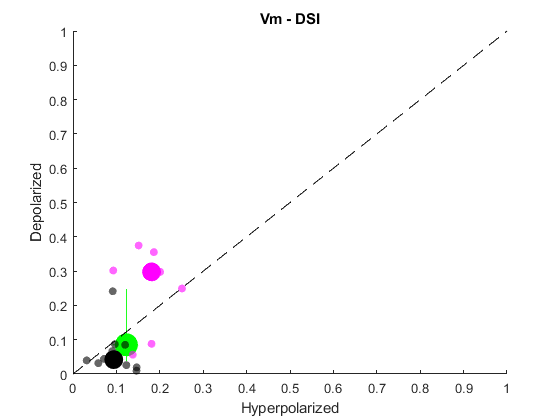


medianX = median([upMax_DSI_hyperpolarized, downMax_DSI_hyperpolarized]);
medianY = median([upMax_DSI_depolarized, downMax_DSI_depolarized]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([upMax_DSI_hyperpolarized, downMax_DSI_hyperpolarized], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([upMax_DSI_depolarized, downMax_DSI_depolarized], 10000);


figure
title('Vm - DSI')
hold on
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
plot([0, 1], [0, 1], '--k')
scatter(upMax_DSI_hyperpolarized, upMax_DSI_depolarized, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(upMax_DSI_hyperpolarized), median(upMax_DSI_depolarized), 200, 'k', 'filled')
scatter(downMax_DSI_hyperpolarized, downMax_DSI_depolarized, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(downMax_DSI_hyperpolarized), median(downMax_DSI_depolarized), 200, 'm', 'filled')
xlabel('Hyperpolarized')
ylabel('Depolarized')
xlim([0, 1])
ylim([0, 1])

p_Vm_DSI = signrank([downMax_DSI_hyperpolarized-downMax_DSI_depolarized,...
    upMax_DSI_hyperpolarized-upMax_DSI_depolarized])

p_Vm_DSI = 0.9058


meanDSIUp = mean([upMax_DSI_hyperpolarized; upMax_DSI_depolarized]);
meanDSIDown =mean([downMax_DSI_hyperpolarized; downMax_DSI_depolarized]);
p_UpVsDown_Mean = ranksum(meanDSIUp, meanDSIDown)

p_UpVsDown_Mean = 7.1987e-04

## Compare the offset data

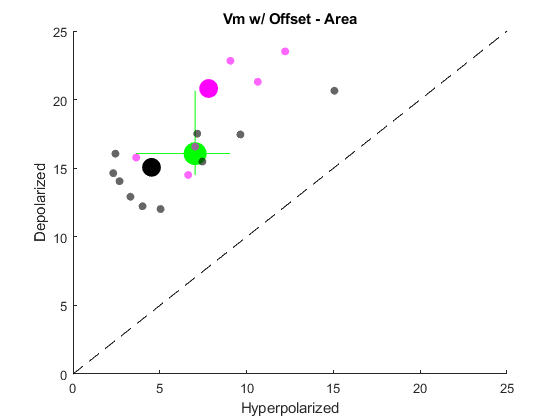

medianX = median([upMax_Area_hyperpolarized_offset, downMax_Area_hyperpolarized_offset]);
medianY = median([upMax_Area_depolarized_offset, downMax_Area_depolarized_offset]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([upMax_Area_hyperpolarized_offset, downMax_Area_hyperpolarized_offset], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([upMax_Area_depolarized_offset, downMax_Area_depolarized_offset], 10000);


figure
title('Vm w/ Offset - Area')
hold on
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
plot([0, 25], [0, 25], '--k')
scatter(upMax_Area_hyperpolarized_offset, upMax_Area_depolarized_offset, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(upMax_Area_hyperpolarized_offset), median(upMax_Area_depolarized_offset), 200, 'k', 'filled')
scatter(downMax_Area_hyperpolarized_offset, downMax_Area_depolarized_offset, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(downMax_Area_hyperpolarized_offset), median(downMax_Area_depolarized_offset), 200, 'm', 'filled')
xlabel('Hyperpolarized')
ylabel('Depolarized')
xlim([0, 25])
ylim([0, 25])

p_Vm_Area_offset = signrank([downMax_Area_hyperpolarized_offset - downMax_Area_depolarized_offset,...
    upMax_Area_hyperpolarized_offset - upMax_Area_depolarized_offset])

p_Vm_Area_offset = 2.9305e-04

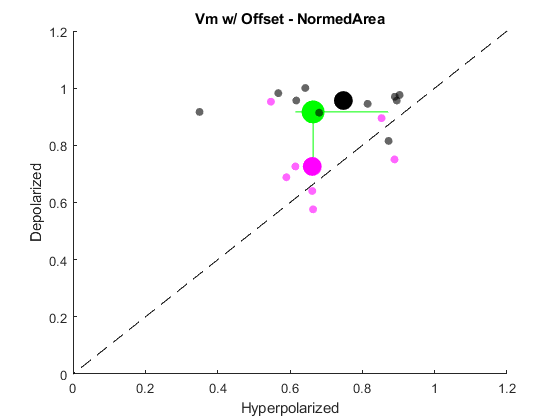


medianX = median([upMax_NormedArea_hyperpolarized_offset, downMax_NormedArea_hyperpolarized_offset]);
medianY = median([upMax_NormedArea_depolarized_offset, downMax_NormedArea_depolarized_offset]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([upMax_NormedArea_hyperpolarized_offset, downMax_NormedArea_hyperpolarized_offset], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([upMax_NormedArea_depolarized_offset, downMax_NormedArea_depolarized_offset], 10000);


figure
title('Vm w/ Offset - NormedArea')
hold on
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
plot([0, 25], [0, 25], '--k')
scatter(upMax_NormedArea_hyperpolarized_offset, upMax_NormedArea_depolarized_offset, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(upMax_NormedArea_hyperpolarized_offset), median(upMax_NormedArea_depolarized_offset), 200, 'k', 'filled')
scatter(downMax_NormedArea_hyperpolarized_offset, downMax_NormedArea_depolarized_offset, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(downMax_NormedArea_hyperpolarized_offset), median(downMax_NormedArea_depolarized_offset), 200, 'm', 'filled')
xlabel('Hyperpolarized')
ylabel('Depolarized')
xlim([0, 1.2])
ylim([0, 1.2])

p_Vm_NormedArea_offset = signrank([downMax_NormedArea_hyperpolarized_offset - downMax_NormedArea_depolarized_offset,...
    upMax_NormedArea_hyperpolarized_offset - upMax_NormedArea_depolarized_offset])

p_Vm_NormedArea_offset = 0.0099

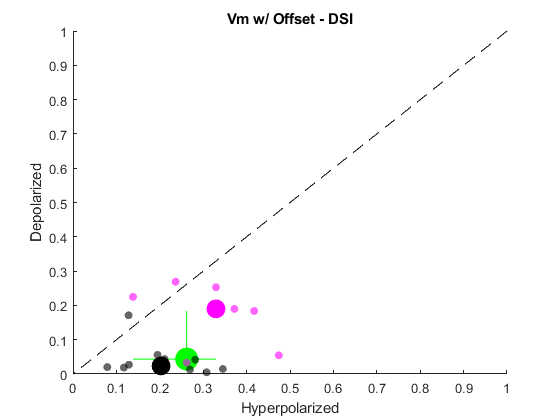


medianX = median([upMax_DSI_hyperpolarized_offset, downMax_DSI_hyperpolarized_offset]);
medianY = median([upMax_DSI_depolarized_offset, downMax_DSI_depolarized_offset]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([upMax_DSI_hyperpolarized_offset, downMax_DSI_hyperpolarized_offset], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([upMax_DSI_depolarized_offset, downMax_DSI_depolarized_offset], 10000);


figure
title('Vm w/ Offset - DSI')
hold on
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
plot([0, 25], [0, 25], '--k')
scatter(upMax_DSI_hyperpolarized_offset, upMax_DSI_depolarized_offset, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(upMax_DSI_hyperpolarized_offset), median(upMax_DSI_depolarized_offset), 200, 'k', 'filled')
scatter(downMax_DSI_hyperpolarized_offset, downMax_DSI_depolarized_offset, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(downMax_DSI_hyperpolarized_offset), median(downMax_DSI_depolarized_offset), 200, 'm', 'filled')
xlabel('Hyperpolarized')
ylabel('Depolarized')
xlim([0, 1])
ylim([0, 1])

p_Vm_DSI_offset = signrank([downMax_DSI_hyperpolarized_offset - downMax_DSI_depolarized_offset,...
    upMax_DSI_hyperpolarized_offset - upMax_DSI_depolarized_offset])

p_Vm_DSI_offset = 0.0012

## Compare the thresholded data

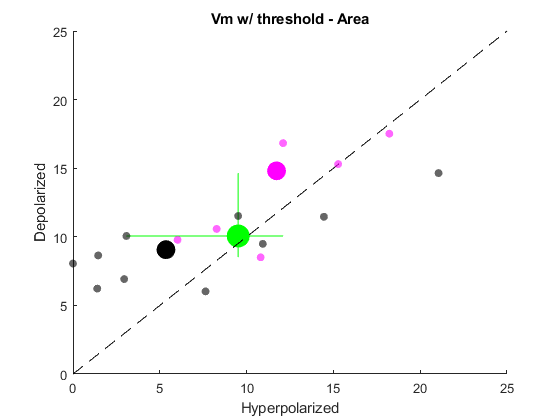

medianX = median([upMax_Area_hyperpolarized_threshold, downMax_Area_hyperpolarized_threshold]);
medianY = median([upMax_Area_depolarized_threshold, downMax_Area_depolarized_threshold]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([upMax_Area_hyperpolarized_threshold, downMax_Area_hyperpolarized_threshold], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([upMax_Area_depolarized_threshold, downMax_Area_depolarized_threshold], 10000);


figure
title('Vm w/ threshold - Area')
hold on
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
plot([0, 25], [0, 25], '--k')
scatter(upMax_Area_hyperpolarized_threshold, upMax_Area_depolarized_threshold, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(upMax_Area_hyperpolarized_threshold), median(upMax_Area_depolarized_threshold), 200, 'k', 'filled')
scatter(downMax_Area_hyperpolarized_threshold, downMax_Area_depolarized_threshold, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(downMax_Area_hyperpolarized_threshold), median(downMax_Area_depolarized_threshold), 200, 'm', 'filled')
xlabel('Hyperpolarized')
ylabel('Depolarized')
xlim([0, 25])
ylim([0, 25])

p_Vm_Area_threshold = signrank([downMax_Area_hyperpolarized_threshold - downMax_Area_depolarized_threshold,...
    upMax_Area_hyperpolarized_threshold - upMax_Area_depolarized_threshold])

p_Vm_Area_threshold = 0.0684

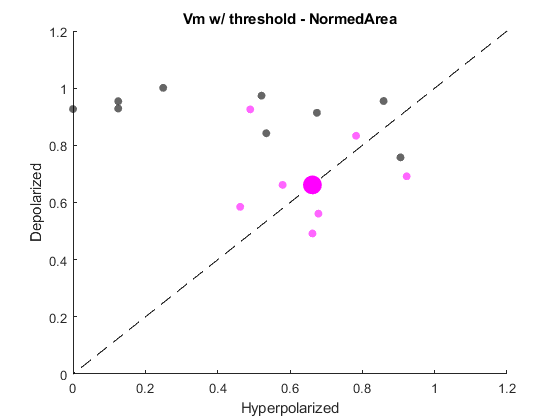



medianX = median([upMax_NormedArea_hyperpolarized_threshold, downMax_NormedArea_hyperpolarized_threshold]);
medianY = median([upMax_NormedArea_depolarized_threshold, downMax_NormedArea_depolarized_threshold]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([upMax_NormedArea_hyperpolarized_threshold, downMax_NormedArea_hyperpolarized_threshold], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([upMax_NormedArea_depolarized_threshold, downMax_NormedArea_depolarized_threshold], 10000);


figure
title('Vm w/ threshold - NormedArea')
hold on
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
plot([0, 25], [0, 25], '--k')
scatter(upMax_NormedArea_hyperpolarized_threshold, upMax_NormedArea_depolarized_threshold, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(upMax_NormedArea_hyperpolarized_threshold), median(upMax_NormedArea_depolarized_threshold), 200, 'k', 'filled')
scatter(downMax_NormedArea_hyperpolarized_threshold, downMax_NormedArea_depolarized_threshold, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(downMax_NormedArea_hyperpolarized_threshold), median(downMax_NormedArea_depolarized_threshold), 200, 'm', 'filled')
xlabel('Hyperpolarized')
ylabel('Depolarized')
xlim([0, 1.2])
ylim([0, 1.2])

p_Vm_NormedArea_threshold = signrank([downMax_NormedArea_hyperpolarized_threshold - downMax_NormedArea_depolarized_threshold,...
    upMax_NormedArea_hyperpolarized_threshold - upMax_NormedArea_depolarized_threshold])

p_Vm_NormedArea_threshold = 0.0262

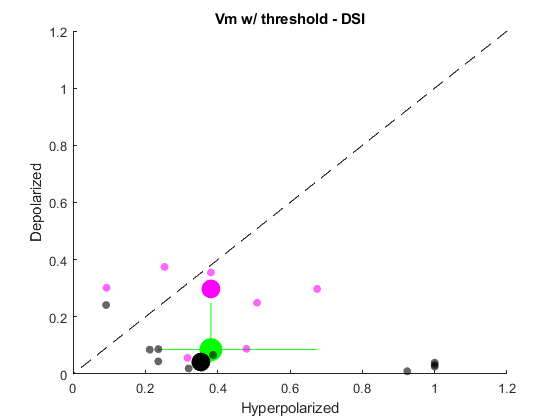


medianX = median([upMax_DSI_hyperpolarized_threshold, downMax_DSI_hyperpolarized_threshold]);
medianY = median([upMax_DSI_depolarized_threshold, downMax_DSI_depolarized_threshold]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([upMax_DSI_hyperpolarized_threshold, downMax_DSI_hyperpolarized_threshold], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([upMax_DSI_depolarized_threshold, downMax_DSI_depolarized_threshold], 10000);


figure
title('Vm w/ threshold - DSI')
hold on
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
plot([0, 25], [0, 25], '--k')
scatter(upMax_DSI_hyperpolarized_threshold, upMax_DSI_depolarized_threshold, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(upMax_DSI_hyperpolarized_threshold), median(upMax_DSI_depolarized_threshold), 200, 'k', 'filled')
scatter(downMax_DSI_hyperpolarized_threshold, downMax_DSI_depolarized_threshold, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(downMax_DSI_hyperpolarized_threshold), median(downMax_DSI_depolarized_threshold), 200, 'm', 'filled')
xlabel('Hyperpolarized')
ylabel('Depolarized')
xlim([0, 1.2])
ylim([0, 1.2])

p_Vm_DSI_threshold = signrank([downMax_DSI_hyperpolarized_threshold - downMax_DSI_depolarized_threshold,...
    upMax_DSI_hyperpolarized_threshold - upMax_DSI_depolarized_threshold])

p_Vm_DSI_threshold = 0.0031

## All data in one plot for each metric


% figure
% title('DSI for Spikes and Vm, hyperpolarized + depolarized')
% hold on
%
% %plot lines connecting points from same cells first
% for i = 1:size(upSpikeHypDep_DSI, 2) %ups
%     plot([upSpikeHypDep_DSI(1, i) upSpikeHypDep_DSI(2, i)], [upSpikeHypDep_DSI(3, i) upSpikeHypDep_DSI(4, i)], 'Color', [0.85, 0.85, 0.85], 'MarkerSize', 0.1, 'HandleVisibility', 'off') %connect the points
% end
%
% for i = 1:size(downSpikeHypDep_DSI, 2) %downs
%     plot([downSpikeHypDep_DSI(1, i), downSpikeHypDep_DSI(2, i)], [downSpikeHypDep_DSI(3, i), downSpikeHypDep_DSI(4, i)], 'Color', [0.85, 0.85, 0.85], 'MarkerSize', 0.1, 'HandleVisibility', 'off') %connect the points
% end
%
% %scastter points for each cell
% %ups
% scatter(upSpikeHypDep_DSI(1, :), upSpikeHypDep_DSI(3, :), 'MarkerEdgeColor','k', 'LineWidth', 1.2, 'MarkerFaceColor', [220, 142, 59]/255, 'MarkerFaceAlpha', 0.7) %spike points
% scatter(upSpikeHypDep_DSI(2, :), upSpikeHypDep_DSI(4, :), 'MarkerEdgeColor','k', 'LineWidth', 1.2, 'MarkerFaceColor', [101, 204, 255]/255, 'MarkerFaceAlpha', 0.7) %Vm points
% %downs
% scatter(downSpikeHypDep_DSI(1, :), downSpikeHypDep_DSI(3, :), 'MarkerEdgeColor', [0.7, 0, 0.7], 'LineWidth', 1.2, 'MarkerFaceColor', [220, 142, 59]/255, 'MarkerFaceAlpha', 0.7) %spike points
% scatter(downSpikeHypDep_DSI(2, :), downSpikeHypDep_DSI(4, :), 'MarkerEdgeColor',[0.7, 0, 0.7], 'LineWidth', 1.2, 'MarkerFaceColor', [101, 204, 255]/255, 'MarkerFaceAlpha', 0.7) %Vm points
%
% %Scatter medians for each condition
% %Scatter medians for each condition
%
% %plot unity line
% plot([0, 1], [0, 1], '--k', 'HandleVisibility', 'off')
%
% scatter(median([upSpikeHypDep_DSI(1, :), downSpikeHypDep_DSI(1, :)]), median([upSpikeHypDep_DSI(3, :) downSpikeHypDep_DSI(3, :)]...
%     ), 300, 'MarkerEdgeColor', [1, 1, 1], 'LineWidth', 0.1, 'MarkerFaceColor', [220, 142, 59]/255) %spike median
% scatter(median([upSpikeHypDep_DSI(2, :), downSpikeHypDep_DSI(2, :)]), median([upSpikeHypDep_DSI(4, :), downSpikeHypDep_DSI(4, :)])...
%     , 300, 'MarkerEdgeColor',  [1, 1, 1], 'LineWidth', 0.1, 'MarkerFaceColor', [101, 204, 255]/255) %Vm median
%
% l = legend({'Up Spikes', 'Up Vm', 'Down Spikes', 'Down Vm'});
% l.Location = 'bestoutside';
% xlim([0 1])
% ylim([0, 1])
% xlabel('Hyperpolarized')
% ylabel('Depolarized')
%
% figure
% title('Normalized Area for Spikes and Vm, hyperpolarized + depolarized')
% hold on
%
% %plot lines connecting points from same cells first
% for i = 1:size(upSpikeHypDep_NormedArea, 2) %ups
%     plot([upSpikeHypDep_NormedArea(1, i) upSpikeHypDep_NormedArea(2, i)], [upSpikeHypDep_NormedArea(3, i) upSpikeHypDep_NormedArea(4, i)], 'Color', [0.85, 0.85, 0.85], 'MarkerSize', 0.1, 'HandleVisibility', 'off') %connect the points
% end
%
% for i = 1:size(downSpikeHypDep_NormedArea, 2) %downs
%     plot([downSpikeHypDep_NormedArea(1, i), downSpikeHypDep_NormedArea(2, i)], [downSpikeHypDep_NormedArea(3, i), downSpikeHypDep_NormedArea(4, i)], 'Color', [0.85, 0.85, 0.85], 'MarkerSize', 0.1, 'HandleVisibility', 'off') %connect the points
% end
%
% %scastter points for each cell
% %ups
% scatter(upSpikeHypDep_NormedArea(1, :), upSpikeHypDep_NormedArea(3, :), 'MarkerEdgeColor','k', 'LineWidth', 1.2, 'MarkerFaceColor', [220, 142, 59]/255, 'MarkerFaceAlpha', 0.7) %spike points
% scatter(upSpikeHypDep_NormedArea(2, :), upSpikeHypDep_NormedArea(4, :), 'MarkerEdgeColor','k', 'LineWidth', 1.2, 'MarkerFaceColor', [101, 204, 255]/255, 'MarkerFaceAlpha', 0.7) %Vm points
% %downs
% scatter(downSpikeHypDep_NormedArea(1, :), downSpikeHypDep_NormedArea(3, :), 'MarkerEdgeColor', [0.7, 0, 0.7], 'LineWidth', 1.2, 'MarkerFaceColor', [220, 142, 59]/255, 'MarkerFaceAlpha', 0.7) %spike points
% scatter(downSpikeHypDep_NormedArea(2, :), downSpikeHypDep_NormedArea(4, :), 'MarkerEdgeColor',[0.7, 0, 0.7], 'LineWidth', 1.2, 'MarkerFaceColor', [101, 204, 255]/255, 'MarkerFaceAlpha', 0.7) %Vm points
%
% %plot unity line
% plot([0, 1.2], [0, 1.2], '--k', 'HandleVisibility', 'off')
%
% %Scatter medians for each condition
% scatter(median([upSpikeHypDep_NormedArea(1, :), downSpikeHypDep_NormedArea(1, :)]), median([upSpikeHypDep_NormedArea(3, :) downSpikeHypDep_NormedArea(3, :)]...
%     ), 300, 'MarkerEdgeColor', [1, 1, 1], 'LineWidth', 0.1, 'MarkerFaceColor', [220, 142, 59]/255) %spike median
% scatter(median([upSpikeHypDep_NormedArea(2, :), downSpikeHypDep_NormedArea(2, :)]), median([upSpikeHypDep_NormedArea(4, :), downSpikeHypDep_NormedArea(4, :)])...
%     , 300, 'MarkerEdgeColor',  [1, 1, 1], 'LineWidth', 0.1, 'MarkerFaceColor', [101, 204, 255]/255) %Vm median
%
% l = legend({'Up Spikes', 'Up Vm', 'Down Spikes', 'Down Vm'});
% l.Location = 'bestoutside';
% xlim([0 1.2])
% ylim([0, 1.2])
% xlabel('Hyperpolarized')
% ylabel('Depolarized')

## Residuals

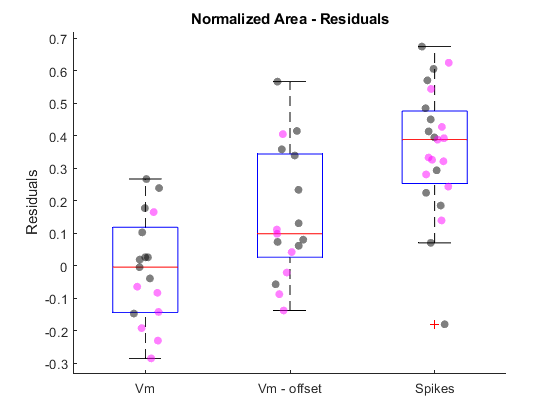

close all
% Analygous metric is the distance from the unity line of each point

%This equation calculates the fractional distance that a point is from the
%unity line (i.e. the distance it is from the nearest point on the unity
%line, divided by the maximum distance that a point can be from unity given
%how close it is to the origin. A point x, y will intersect the unity line
%at the ordered pair <(x+y)/2, (x+y)/2>. So the first part of the
%calculation is simply the distance formula of this ordered pair versus the
%point (x,y). This number is then divided by the distance of <(x+y)/2,
%(x+y)/2> from the origin to get the fractiona distance.

% fractionalDistanceFromUnity = @(x, y) sqrt((x - (x+y)/2).^2 + (y - (x+y)/2).^2)./sqrt(2*((x+y)./2).^2);

residualIndex = @(x,y) (x-y);%./(x+y));
upVmResiduals = residualIndex(upMax_NormedArea_depolarized, upMax_NormedArea_hyperpolarized);
downVmResiduals = residualIndex(downMax_NormedArea_depolarized, downMax_NormedArea_hyperpolarized);

upVmResiduals_offset = residualIndex(upMax_NormedArea_depolarized_offset, upMax_NormedArea_hyperpolarized_offset);
downVmResiduals_offset = residualIndex(downMax_NormedArea_depolarized_offset, downMax_NormedArea_hyperpolarized_offset);

upVmResiduals_threshold = residualIndex(upMax_NormedArea_depolarized_threshold, upMax_NormedArea_hyperpolarized_threshold);
downVmResiduals_threshold = residualIndex(downMax_NormedArea_depolarized_threshold, downMax_NormedArea_hyperpolarized_threshold);

upSpikeResiduals = residualIndex(upNormalizedDPAreas, upNormalizedHPAreas);
downSpikeResiduals = residualIndex(downNormalizedDPAreas, downNormalizedHPAreas);

allResiduals = [upVmResiduals, downVmResiduals, upVmResiduals_offset, downVmResiduals_offset, upSpikeResiduals', downSpikeResiduals'];
%allResiduals = [upVmResiduals, downVmResiduals, upVmResiduals_offset, downVmResiduals_offset, upVmResiduals_threshold, downVmResiduals_threshold, upSpikeResiduals', downSpikeResiduals'];

groupIDs = zeros(1, numel(allResiduals));
groupIDs(numel(upVmResiduals) + numel(downVmResiduals) + 1:end) = 1;
groupIDs(numel(upVmResiduals) + numel(downVmResiduals) + numel(upVmResiduals_offset) + numel(downVmResiduals_offset) + 1:end) = 2;
% groupIDs(numel(upVmResiduals) + numel(downVmResiduals) + numel(upVmResiduals_offset) + numel(downVmResiduals_offset) +...
%     numel(upVmResiduals_offset) + numel(downVmResiduals_offset) +  1:end) = 3;

figure
title('Normalized Area - Residuals')
hold on
boxplot(allResiduals, groupIDs)
%scatter Vm points
scatter(ones(size(upVmResiduals)).*(1+(rand(size(upVmResiduals))-0.5)/5),upVmResiduals,'k','filled', 'MarkerFaceAlpha', 0.5)
scatter(ones(size(downVmResiduals)).*(1+(rand(size(downVmResiduals))-0.5)/5),downVmResiduals,'m','filled', 'MarkerFaceAlpha', 0.5)
%scatter offset Vms
scatter(ones(size(upVmResiduals_offset)).*(1+(rand(size(upVmResiduals_offset))-0.5)/5)+ 1,upVmResiduals_offset,'k','filled', 'MarkerFaceAlpha', 0.5)
scatter(ones(size(downVmResiduals_offset)).*(1+(rand(size(downVmResiduals_offset))-0.5)/5) + 1,downVmResiduals_offset,'m','filled', 'MarkerFaceAlpha', 0.5)
%scatter threshold Vms
%scatter(ones(size(upVmResiduals_threshold)).*(1+(rand(size(upVmResiduals_threshold))-0.5)/5)+ 2,upVmResiduals_threshold,'k','filled', 'MarkerFaceAlpha', 0.5)
%scatter(ones(size(downVmResiduals_threshold)).*(1+(rand(size(downVmResiduals_threshold))-0.5)/5) + 2,downVmResiduals_threshold,'m','filled', 'MarkerFaceAlpha', 0.5)
%scatter spike points
scatter(ones(size(upSpikeResiduals)).*(1+(rand(size(upSpikeResiduals))-0.5)/5) + 2,upSpikeResiduals,'k','filled', 'MarkerFaceAlpha', 0.5)
scatter(ones(size(downSpikeResiduals)).*(1+(rand(size(downSpikeResiduals))-0.5)/5) + 2,downSpikeResiduals,'m','filled', 'MarkerFaceAlpha', 0.5)
xticklabels({'Vm', 'Vm - offset', 'Spikes'})
ylabel('Residuals')
box off

p_Vm = signrank([upVmResiduals, downVmResiduals])

p_Vm = 0.7946

p_Vm_offset = signrank([upVmResiduals_offset, downVmResiduals_offset])

p_Vm_offset = 0.0099

p_Vm_threshold = signrank([upVmResiduals_threshold, downVmResiduals_threshold])

p_Vm_threshold = 0.0262


p_spike = signrank([upSpikeResiduals; downSpikeResiduals])

p_spike = 4.0254e-05

p_Vm_vs_VmOffset = ranksum([upVmResiduals, downVmResiduals], [upVmResiduals_offset, downVmResiduals_offset])

p_Vm_vs_VmOffset = 0.0230


p_Vm_vs_Spike = ranksum([upVmResiduals, downVmResiduals], [upSpikeResiduals; downSpikeResiduals]) %change this to a sign rank test

p_Vm_vs_Spike = 4.8992e-06

p_VmOffset_vs_Spike = ranksum([upVmResiduals_offset, downVmResiduals_offset], [upSpikeResiduals; downSpikeResiduals])

p_VmOffset_vs_Spike = 0.0044

p_VmOffset_vs_Threshold = ranksum([upVmResiduals_threshold downVmResiduals_threshold],[downVmResiduals_offset upVmResiduals_offset])

p_VmOffset_vs_Threshold = 0.4824

p_VmThreshold_vs_Spike = ranksum([upVmResiduals_threshold downVmResiduals_threshold],[downSpikeResiduals; upSpikeResiduals])

p_VmThreshold_vs_Spike = 0.3108

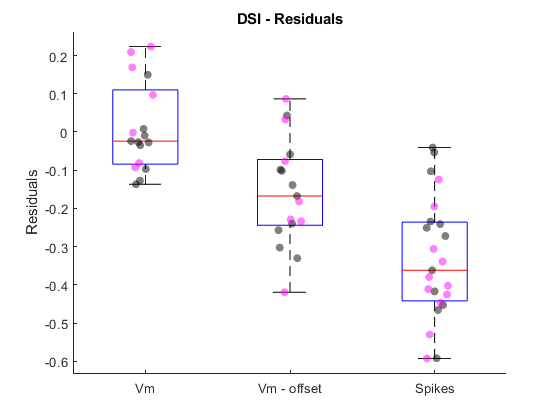


upVmResiduals = residualIndex(upMax_DSI_depolarized, upMax_DSI_hyperpolarized);
downVmResiduals = residualIndex(downMax_DSI_depolarized, downMax_DSI_hyperpolarized);

upVmResiduals_offset = residualIndex(upMax_DSI_depolarized_offset, upMax_DSI_hyperpolarized_offset);
downVmResiduals_offset = residualIndex(downMax_DSI_depolarized_offset, downMax_DSI_hyperpolarized_offset);

upVmResiduals_threshold = residualIndex(upMax_DSI_depolarized_threshold, upMax_DSI_hyperpolarized_threshold);
downVmResiduals_threshold = residualIndex(downMax_DSI_depolarized_threshold, downMax_DSI_hyperpolarized_threshold);

upSpikeResiduals = residualIndex(upDPDSIs, upHPDSIs);
downSpikeResiduals = residualIndex(downDPDSIs, downHPDSIs);

%allResiduals = [upVmResiduals, downVmResiduals, upVmResiduals_offset, downVmResiduals_offset, upVmResiduals_threshold, downVmResiduals_threshold, upSpikeResiduals', downSpikeResiduals'];
allResiduals = [upVmResiduals, downVmResiduals, upVmResiduals_offset, downVmResiduals_offset, upSpikeResiduals', downSpikeResiduals'];

groupIDs = zeros(1, numel(allResiduals));
groupIDs(numel(upVmResiduals) + numel(downVmResiduals) + 1:end) = 1;
groupIDs(numel(upVmResiduals) + numel(downVmResiduals) + numel(upVmResiduals_offset) + numel(downVmResiduals_offset) + 1:end) = 2;
%groupIDs(numel(upVmResiduals) + numel(downVmResiduals) + numel(upVmResiduals_offset) + numel(downVmResiduals_offset) +...
%    numel(upVmResiduals_offset) + numel(downVmResiduals_offset) +  1:end) = 3;

figure
title('DSI - Residuals')
hold on
boxplot(allResiduals, groupIDs)
%scatter Vm points
scatter(ones(size(upVmResiduals)).*(1+(rand(size(upVmResiduals))-0.5)/5),upVmResiduals,'k','filled', 'MarkerFaceAlpha', 0.5)
scatter(ones(size(downVmResiduals)).*(1+(rand(size(downVmResiduals))-0.5)/5),downVmResiduals,'m','filled', 'MarkerFaceAlpha', 0.5)
%scatter offset Vms
scatter(ones(size(upVmResiduals_offset)).*(1+(rand(size(upVmResiduals_offset))-0.5)/5)+ 1,upVmResiduals_offset,'k','filled', 'MarkerFaceAlpha', 0.5)
scatter(ones(size(downVmResiduals_offset)).*(1+(rand(size(downVmResiduals_offset))-0.5)/5) + 1,downVmResiduals_offset,'m','filled', 'MarkerFaceAlpha', 0.5)
%scatter threshold Vms
%scatter(ones(size(upVmResiduals_threshold)).*(1+(rand(size(upVmResiduals_threshold))-0.5)/5)+ 2,upVmResiduals_threshold,'k','filled', 'MarkerFaceAlpha', 0.5)
%scatter(ones(size(downVmResiduals_threshold)).*(1+(rand(size(downVmResiduals_threshold))-0.5)/5) + 2,downVmResiduals_threshold,'m','filled', 'MarkerFaceAlpha', 0.5)
%scatter spike points
scatter(ones(size(upSpikeResiduals)).*(1+(rand(size(upSpikeResiduals))-0.5)/5) + 2,upSpikeResiduals,'k','filled', 'MarkerFaceAlpha', 0.5)
scatter(ones(size(downSpikeResiduals)).*(1+(rand(size(downSpikeResiduals))-0.5)/5) + 2,downSpikeResiduals,'m','filled', 'MarkerFaceAlpha', 0.5)
ylabel('Residuals')
box off
xticklabels({'Vm', 'Vm - offset', 'Spikes'})

p_Vm = signrank([upVmResiduals, downVmResiduals])

p_Vm = 0.9058

p_Vm_offset = signrank([upVmResiduals_offset, downVmResiduals_offset])

p_Vm_offset = 0.0012

p_Vm_threshold = signrank([upVmResiduals_threshold, downVmResiduals_threshold])

p_Vm_threshold = 0.0031

p_spike = signrank([upSpikeResiduals; downSpikeResiduals])

p_spike = 2.7016e-05

p_Vm_vs_VmOffset = ranksum([upVmResiduals, downVmResiduals], [upVmResiduals_offset, downVmResiduals_offset])

p_Vm_vs_VmOffset = 0.0012


p_Vm_vs_Spike = ranksum([upVmResiduals, downVmResiduals], [upSpikeResiduals; downSpikeResiduals]) %change this to a sign rank test

p_Vm_vs_Spike = 7.3419e-07

p_VmOffset_vs_Spike = ranksum([upVmResiduals_offset, downVmResiduals_offset], [upSpikeResiduals; downSpikeResiduals])

p_VmOffset_vs_Spike = 0.0015

p_VmOffset_vs_Threshold = ranksum([upVmResiduals_threshold downVmResiduals_threshold],[downVmResiduals_offset upVmResiduals_offset])

p_VmOffset_vs_Threshold = 0.1683

p_VmThreshold_vs_Spike = ranksum([upVmResiduals_threshold downVmResiduals_threshold],[downSpikeResiduals; upSpikeResiduals])

p_VmThreshold_vs_Spike = 0.3964


%close all %This script is so big that figures need to close in order to save enough memory

## Compare spike data to Vm data

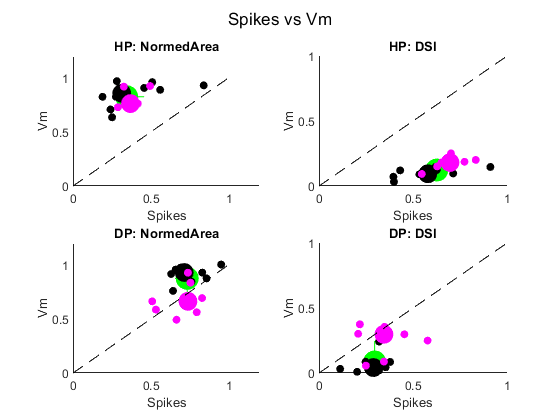


figure
sgtitle('Spikes vs Vm')
hold on

medianX = median([upSpikeHypDep_NormedArea(1, :), downSpikeHypDep_NormedArea(1, :)]);
medianY = median([upSpikeHypDep_NormedArea(2, :), downSpikeHypDep_NormedArea(2, :)]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([upSpikeHypDep_NormedArea(1, :), downSpikeHypDep_NormedArea(1, :)], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([upSpikeHypDep_NormedArea(2, :), downSpikeHypDep_NormedArea(2, :)], 10000);

subplot(2, 2, 1)
title('HP: NormedArea')
hold on
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
scatter(upSpikeHypDep_NormedArea(1, :), upSpikeHypDep_NormedArea(2, :), 'k', 'filled')
scatter(median(upSpikeHypDep_NormedArea(1, :)), median(upSpikeHypDep_NormedArea(2, :)), 200, 'k', 'filled')
scatter(downSpikeHypDep_NormedArea(1, :), downSpikeHypDep_NormedArea(2, :), 'm', 'filled')
scatter(median(downSpikeHypDep_NormedArea(1, :)), median(downSpikeHypDep_NormedArea(2, :)), 200, 'm', 'filled')
plot([0, 1], [0, 1], '--k')
xlabel('Spikes')
ylabel('Vm')
xlim([0, 1.2])
ylim([0, 1.2])

p_hyperpolarized_NormedArea = signrank([upSpikeHypDep_NormedArea(1, :) - upSpikeHypDep_NormedArea(2, :),...
    downSpikeHypDep_NormedArea(1, :) - downSpikeHypDep_NormedArea(2, :)]);

medianX = median([upSpikeHypDep_NormedArea(3, :), downSpikeHypDep_NormedArea(3, :)]);
medianY = median([upSpikeHypDep_NormedArea(4, :), downSpikeHypDep_NormedArea(4, :)]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([upSpikeHypDep_NormedArea(3, :), downSpikeHypDep_NormedArea(3, :)], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([upSpikeHypDep_NormedArea(4, :), downSpikeHypDep_NormedArea(4, :)], 10000);

subplot(2, 2, 3)
title('DP: NormedArea')
hold on
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
scatter(upSpikeHypDep_NormedArea(3, :), upSpikeHypDep_NormedArea(4, :), 'k', 'filled')
scatter(median(upSpikeHypDep_NormedArea(3, :)), median(upSpikeHypDep_NormedArea(4, :)), 200, 'k', 'filled')
scatter(downSpikeHypDep_NormedArea(3, :), downSpikeHypDep_NormedArea(4, :), 'm', 'filled')
scatter(median(downSpikeHypDep_NormedArea(3, :)), median(downSpikeHypDep_NormedArea(4, :)), 200, 'm', 'filled')
plot([0, 1], [0, 1], '--k')
xlabel('Spikes')
ylabel('Vm')
xlim([0, 1.2])
ylim([0, 1.2])

p_depolarized_NormedArea = signrank([upSpikeHypDep_NormedArea(3, :) - upSpikeHypDep_NormedArea(4, :),...
    downSpikeHypDep_NormedArea(3, :) - downSpikeHypDep_NormedArea(4, :)]);

medianX = median([upSpikeHypDep_DSI(1, :), downSpikeHypDep_DSI(1, :)]);
medianY = median([upSpikeHypDep_DSI(2, :), downSpikeHypDep_DSI(2, :)]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([upSpikeHypDep_DSI(1, :), downSpikeHypDep_DSI(1, :)], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([upSpikeHypDep_DSI(2, :), downSpikeHypDep_DSI(2, :)], 10000);

subplot(2,2, 2)
title('HP: DSI')
hold on
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
scatter(upSpikeHypDep_DSI(1, :), upSpikeHypDep_DSI(2, :), 'k', 'filled')
scatter(median(upSpikeHypDep_DSI(1, :)), median(upSpikeHypDep_DSI(2, :)), 200, 'k', 'filled')
scatter(downSpikeHypDep_DSI(1, :), downSpikeHypDep_DSI(2, :), 'm', 'filled')
scatter(median(downSpikeHypDep_DSI(1, :)), median(downSpikeHypDep_DSI(2, :)), 200, 'm', 'filled')
plot([0, 1], [0, 1], '--k')
xlabel('Spikes')
ylabel('Vm')
xlim([0, 1])
ylim([0, 1])

p_hyperpolarized_DSI = signrank([upSpikeHypDep_DSI(1, :) - upSpikeHypDep_DSI(2, :),...
    downSpikeHypDep_DSI(1, :) - downSpikeHypDep_DSI(2, :)]);

medianX = median([upSpikeHypDep_DSI(3, :), downSpikeHypDep_DSI(3, :)]);
medianY = median([upSpikeHypDep_DSI(4, :), downSpikeHypDep_DSI(4, :)]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([upSpikeHypDep_DSI(3, :), downSpikeHypDep_DSI(3, :)], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([upSpikeHypDep_DSI(4, :), downSpikeHypDep_DSI(4, :)], 10000);

subplot(2, 2, 4)
title('DP: DSI')
hold on
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2] + medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')
scatter(upSpikeHypDep_DSI(3, :), upSpikeHypDep_DSI(4, :), 'k', 'filled')
scatter(median(upSpikeHypDep_DSI(3, :)), median(upSpikeHypDep_DSI(4, :)), 200, 'k', 'filled')
scatter(downSpikeHypDep_DSI(3, :), downSpikeHypDep_DSI(4, :), 'm', 'filled')
scatter(median(downSpikeHypDep_DSI(3, :)), median(downSpikeHypDep_DSI(4, :)), 200, 'm', 'filled')
plot([0, 1], [0, 1], '--k')
xlabel('Spikes')
ylabel('Vm')
xlim([0, 1])
ylim([0, 1])


p_depolarized_DSI = signrank([upSpikeHypDep_DSI(3, :) - upSpikeHypDep_DSI(4, :),...
    downSpikeHypDep_DSI(3, :) - downSpikeHypDep_DSI(4, :)]);

ps = [p_hyperpolarized_NormedArea, p_hyperpolarized_DSI; p_depolarized_NormedArea, p_depolarized_DSI]

ps =     0.0003    0.0003
    0.0312    0.0019


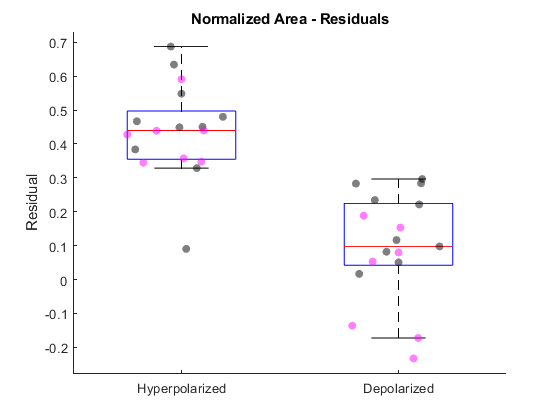

% Residuals for Spikes vs Vm
up_NA_HP_Resids = -residualIndex(upSpikeHypDep_NormedArea(1, :), upSpikeHypDep_NormedArea(2, :));
down_NA_HP_Resids =  -residualIndex(downSpikeHypDep_NormedArea(1, :), downSpikeHypDep_NormedArea(2, :));

up_NA_DP_Resids = -residualIndex(upSpikeHypDep_NormedArea(3, :), upSpikeHypDep_NormedArea(4, :));
down_NA_DP_Resids =  -residualIndex(downSpikeHypDep_NormedArea(3, :), downSpikeHypDep_NormedArea(4, :));

up_DSI_HP_Resids = -residualIndex(upSpikeHypDep_DSI(1, :), upSpikeHypDep_DSI(2, :));
down_DSI_HP_Resids = -residualIndex(downSpikeHypDep_DSI(1, :), downSpikeHypDep_DSI(2, :));

up_DSI_DP_Resids = -residualIndex(upSpikeHypDep_DSI(3, :), upSpikeHypDep_DSI(4, :));
down_DSI_DP_Resids = -residualIndex(downSpikeHypDep_DSI(3, :), downSpikeHypDep_DSI(4, :));


NA_Resids = [up_NA_HP_Resids down_NA_HP_Resids up_NA_DP_Resids down_NA_DP_Resids];
DSI_Resids = [up_DSI_HP_Resids down_DSI_HP_Resids up_DSI_DP_Resids down_DSI_DP_Resids];

groupIDs_NA = zeros(1, numel(NA_Resids));
groupIDs_NA(numel(up_NA_HP_Resids) + numel(down_NA_HP_Resids) + 1:end) = 1;

groupIDs_DSI = zeros(1, numel(DSI_Resids));
groupIDs_DSI(numel(up_DSI_HP_Resids) + numel(down_DSI_HP_Resids) + 1:end) = 1;

figure
title('Normalized Area - Residuals')
hold on
boxplot(NA_Resids, groupIDs_NA, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(size(up_NA_HP_Resids)), up_NA_HP_Resids,'k','filled', 'MarkerFaceAlpha', 0.5, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(size(down_NA_HP_Resids)),down_NA_HP_Resids,'m','filled', 'MarkerFaceAlpha', 0.5, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(size(up_NA_DP_Resids))+1, up_NA_DP_Resids,'k','filled', 'MarkerFaceAlpha', 0.5, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(size(down_NA_DP_Resids))+1, down_NA_DP_Resids,'m','filled', 'MarkerFaceAlpha', 0.5, 'XJitter','density', 'XJitterWidth', 0.5)
box off
ylabel('Residual')
xticklabels({'Hyperpolarized', 'Depolarized'})

p = ranksum([up_NA_HP_Resids, down_NA_HP_Resids], [up_NA_DP_Resids, down_NA_DP_Resids])

p = 3.3213e-06

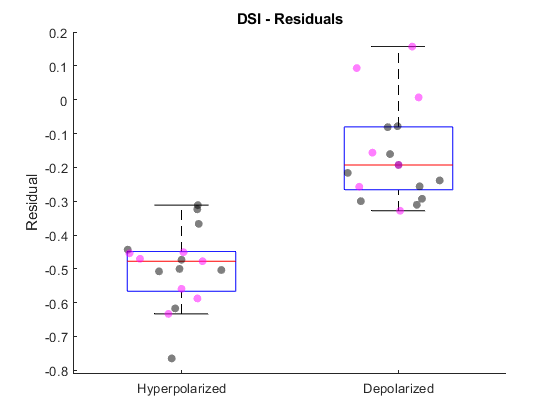


figure
title('DSI - Residuals')
hold on
boxplot(DSI_Resids, groupIDs_DSI, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(size(up_DSI_HP_Resids)), up_DSI_HP_Resids,'k','filled', 'MarkerFaceAlpha', 0.5, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(size(down_DSI_HP_Resids)),down_DSI_HP_Resids,'m','filled', 'MarkerFaceAlpha', 0.5, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(size(up_DSI_DP_Resids))+1, up_DSI_DP_Resids,'k','filled', 'MarkerFaceAlpha', 0.5, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(size(down_DSI_DP_Resids))+1, down_DSI_DP_Resids,'m','filled', 'MarkerFaceAlpha', 0.5, 'XJitter','density', 'XJitterWidth', 0.5)
box off
ylabel('Residual')
xticklabels({'Hyperpolarized', 'Depolarized'})

p = ranksum([up_DSI_HP_Resids, down_DSI_HP_Resids], [up_DSI_DP_Resids, down_DSI_DP_Resids])

p = 1.0033e-06

## Create a table that summarizes the results

%WARNING - IF YOU ARE EXCLUDING ANY CELLS IN THE VM ANALYSIS, THIS SECTION
%OF THE CODE WON'T WORK. GO BACK UP AND MAKE SURE THE VARIABLE CALLED
%cantExtractVmFrom IS TEMPORARILY SET TO BLANK (I.E. {}) IN ORDER TO MAKE THIS SECTION WORK
%Of course, this also means that this section will include the data from
%every cell and won't get rid of the cells that you want to exclude...  but
%you can always do that separately afterwards.

%first make a cell array, fill it with the correct data from UP and DOWN cells, then convert to a table
c = {};

%UP cells first
for i = 1:numel(upNames)
    c{end+1, 1} = upNames(i);
    c{end, 2} = 'Inferior';
    
    %spikes
    c{end, 3} = areaDPUp(i);
    c{end, 4} = areaHPUp(i);
    c{end, 5} = upNormalizedDPAreas(i);
    c{end, 6} = upNormalizedHPAreas(i);
    c{end, 7} = upDPDSIs(i);
    c{end, 8} = upHPDSIs(i);
    
    %Vms
    c{end, 9} = upMax_Area_depolarized(i);
    c{end, 10} = upMax_Area_hyperpolarized(i);
    c{end, 11} = upMax_NormedArea_depolarized(i);
    c{end, 12} = upMax_NormedArea_hyperpolarized(i);
    c{end, 13} = upMax_DSI_depolarized(i);
    c{end, 14} = upMax_DSI_hyperpolarized(i);
end

Index exceeds the number of array elements (10).


%DOWN cells second
for i = 1:numel(downNames)
    c{end+1, 1} = downNames(i);
    c{end, 2} = 'Superior';
    
    %spikes
    c{end, 3} = areaDPDown(i);
    c{end, 4} = areaHPDown(i);
    c{end, 5} = downNormalizedDPAreas(i);
    c{end, 6} = downNormalizedHPAreas(i);
    c{end, 7} = downDPDSIs(i);
    c{end, 8} = downHPDSIs(i);
    
    %Vms
    c{end, 9} = downMax_Area_depolarized(i);
    c{end, 10} = downMax_Area_hyperpolarized(i);
    c{end, 11} = downMax_NormedArea_depolarized(i);
    c{end, 12} = downMax_NormedArea_hyperpolarized(i);
    c{end, 13} = downMax_DSI_depolarized(i);
    c{end, 14} = downMax_DSI_hyperpolarized(i);
end
currentInjectionsResultsTable = cell2table(c, 'VariableNames', {'Cell Name', 'Cell Type', 'Depolarized Spikes Area', 'Hyperpolarized Spikes Area',...
    'Depolarized Spikes Normalized Area', 'Hyperpolarized Spikes Normalized Area',...
    'Depolarized Spikes DSI', 'Hyperpolarized Spikes DSI',...
    'Depolarized Vm Area', 'Hyperpolarized Vm Area',...
    'Depolarized Vm Normalized Area', 'Hyperpolarized Vm Normalized Area',...
    'Depolarized Vm DSI', 'Hyperpolarized Vm DSI'});